load('D:\PolyU\RA\Vehicle dynamics\Vehicle dynamics\Matlab\CarSim outputs\FP FN\LastRunslip_FPFN.mat')
S = load('D:\PolyU\RA\Vehicle dynamics\Vehicle dynamics\Matlab\CarSim outputs\FP FN\simslip_FPFN.mat');

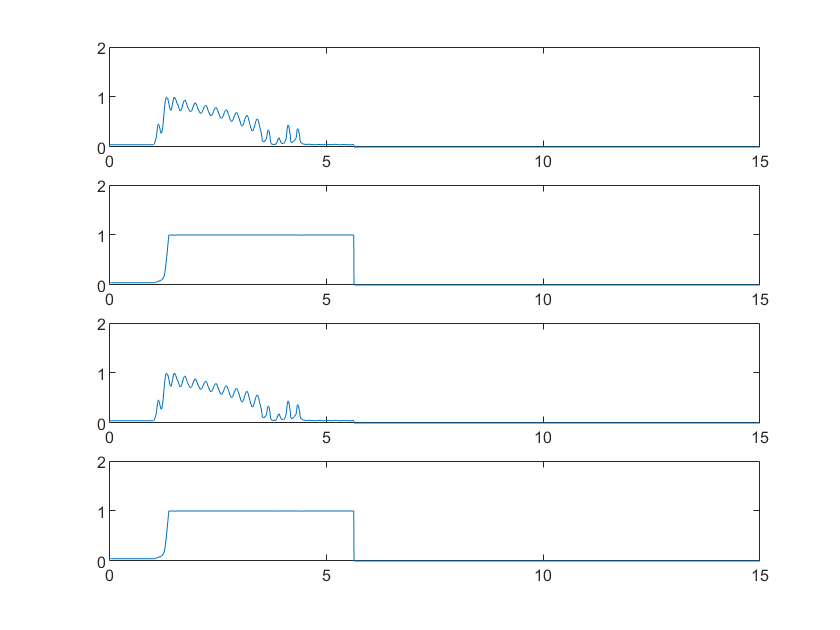

figure
subplot(4,1,1)
plot(S.simSlip.Time, S.simSlip.Data(:,1))
ylim([0 2])
subplot(4,1,2)
ylim([0 2])
plot(S.simSlip.Time, S.simSlip.Data(:,2))
ylim([0 2])
subplot(4,1,3)
plot(S.simSlip.Time, S.simSlip.Data(:,3))
ylim([0 2])
subplot(4,1,4)
plot(S.simSlip.Time, S.simSlip.Data(:,4))
ylim([0 2])

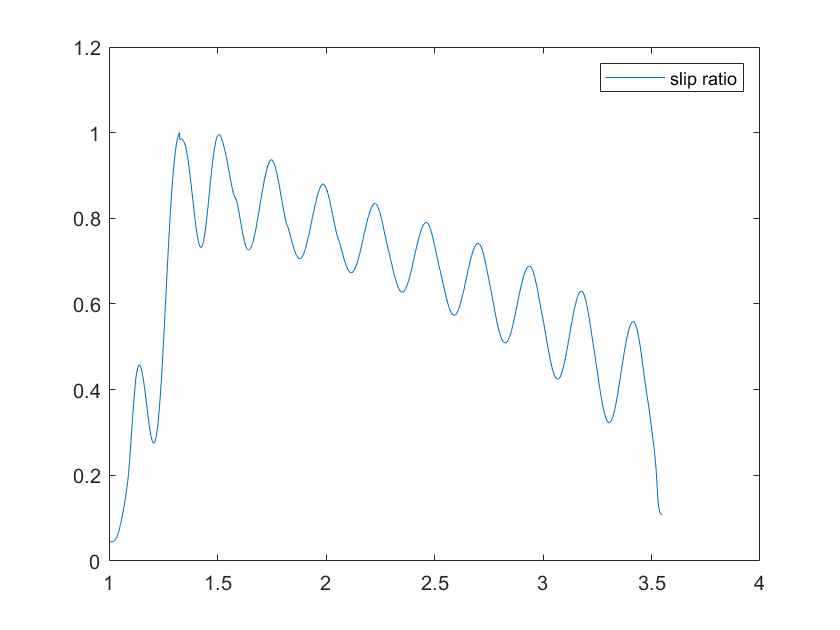

index_attack = and((S.simSlip.Time > 1 ), (S.simSlip.Time < 3.55));


slip_attack = S.simSlip.Data(index_attack,1); 

figure

plot(S.simSlip.Time(index_attack), slip_attack, 'DisplayName','slip ratio')

legend


n_slip_total_attack = length(slip_attack);
FN = [];
for i = 0.1:0.1:0.9
    fn = 100 - length(slip_attack(slip_attack>i)) / n_slip_total_attack * 100;
    FN = [FN;[i, fn]];
end
FN

FN =     0.1000    2.3142
    0.2000    4.5499
    0.3000    7.0602
    0.4000   13.7674
    0.5000   23.0437
    0.6000   36.8308
    0.7000   54.8147
    0.8000   78.2702
    0.9000   91.3905
